# Cone Detection Using Yolov4 Deep Learning for Formula Student Driverless Competition - Herkules Racing Team

This live script can be used to detect FSG compliant codes in the MALAB framework. One can learn the step by step approach of data labeling, training a YOLOv4 Neural Network and deploy trained neural networks to NVIDIA Embedded GPUs.

close all; clear; clc;

## Step 1: Data Label 

Label the images to perform a supervised learning approach. With Image Labeler app or the Video Labeler app one can label the objects. by using the in-built algorithms of the app or by integrating custom algorithms within the app.

The Ground Labeler app has been used to create the ground truth in this example.

%imageLabeler

Once the desired objects are labelled, perform the following steps.

- Export --> To Workspace

- Give the desired variable name (e.g. **gTruth**) in the "**Export variable name**" field

- Keep the **Export format **field as **groundTruth**

Save the exported labels i.e., **gTruth **into a MAT file using the following command.

Note: The file extension of Ground Truth objects would be ***.mat**.

%save('gTruth.mat','gTruth')

In this example, the labelled objects are stored in **gTruth.mat** file.

## Step 2: Convert ground truth object into training data

Load the gTruth object from a saved MAT file. The ground truth is the set of known location of objects of interest in a set of images to be used to train the detector

data = load("gTruth.mat");
gTruthdata = data.gTruth;

Create the following folders

- **TrainingData** for the training data.

- **Output** for storing the results.

if ~isfolder(fullfile("TrainingData"))
    mkdir TrainingData
end
if ~isfolder(fullfile("Output"))
    mkdir Output
end
addpath('TrainingData');
addpath('Output');

Create the training data from the ground truth objects using the in-built function **objectDetectorTrainingData**.

trainingData = objectDetectorTrainingData(gTruthdata,"SamplingFactor","auto",'WriteLocation','TrainingData');

Display first few rows of the data set.

trainingData(1:4,:)

ans = 4×5 table
                                                                 imageFilename                                                                   BlueCone      OrangeConeBig    OrangeConeSmall     YellowCone 
    _______________________________________________________________________________________________________________________________________    ____________    _____________    _______________    ____________

    {'/home/hrt/Documents/HRT/Cone Detection/HRTConeDetection_Matlab/images/BRTtestcut_mp4-4_jpg.rf.ba6f3edda06f7d4e8cd12d5f3f11cb01.jpg' }    {3×4 double}    {3×4 double}      {0×0 double}      {3×4 double}
    {'/home/hrt/Documents/HRT/Cone Detection/HRTConeDetection_Matlab/images/BRTtestcut_mp4-5_jpg.rf.b19342a550695b175921a5e311ce1a25.jpg' }    {2×4 double}    {2×4 double}      {0×0 double}

Create data sets from the training data. Set random seed.

rng(0);

shuffledIndices = randperm(height(trainingData));
idx = floor(0.8 * length(shuffledIndices));

trainingIdx = 1:idx;
testIdx = trainingIdx(end)+1 : length(shuffledIndices);

Shuffle the training data and then split the data into two sets.

trainingDataSet = trainingData(shuffledIndices(trainingIdx),:);
testDataSet = trainingData(shuffledIndices(testIdx),:);

## Step 3: Design Yolov4 Network

### What is a Yolov4 Network?

You only look once (YOLO) is a popular neural network framework used to perform real-time object detection. It is a single stage object detection network which is faster than other two-stage deep learning object detectors, such as regions with convolutional neural networks (Faster R-CNNs).

### Define Input Size

Specify the input size to use for resizing the training images. The size of the training images must be a multiple of 32 for when you use the `tiny-yolov4-coco` and `csp-darknet53-coco` pretrained YOLO v4 deep learning networks. You must also resize the bounding boxes based on the specified input size.

inputSize = [320 320 3];
inputLayer = imageInputLayer(inputSize,'Name','input','Normalization','none');

Compute number of Classes based on Input data.

numClasses = size(trainingData,2) - 1;

### Define Anchor boxes

- The shape, size, and number of anchor boxes used for training impact the efficiency and accuracy of the YOLOv4 object detection network. 

- The anchor boxes must closely represent the sizes and aspect ratios of the objects in the training data. 

- The training data must contain both the ground truth images and labels. 

- The size of the training images must be the same as the network input size, and the bounding box labels must correspond to the size of the training images.

Create an `imageDatastore` using the files from the table.

imds = imageDatastore(trainingDataSet.imageFilename);

Create a `boxLabelDatastore` using the label columns from the table.

blds = boxLabelDatastore(trainingDataSet(:,2:end));

Combine the data stores

datastore = combine(imds,blds);

Resize and rescale the training images and the bounding boxes by using the `preprocessData` helper function. Also, convert the preprocessed data to a `datastore` object by using the `transform` function.

rng("default");
trainingDataForEstimation = transform(datastore,@(gTruthdata)preprocessData(gTruthdata,inputSize));

- Assume that one specifies four anchor boxes for each detection head. 

- Then, the total number of anchor boxes that one can use for training the network must be twelve. 

- One can use the [`estimateAnchorBoxes`](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) function to automatically estimate the anchor boxes for your specified training data.

numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

Compute the area of each anchor box and sort them in descending order.

area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
sortedAnchors = anchors(idx,:);

There are two detection heads in the tiny YOLOv4 network, so make two sets of four anchor boxes each.

anchorBoxes = {sortedAnchors(1:3,:) sortedAnchors(4:6,:) };
% anchorBoxes = cell(anchors,1);

Create a YOLOv4 object detection network by using the `yolov4ObjectDetector` function.

classes = ["BlueCone" "OrangeConeBig" "OrangeConeSmall" "YellowCone"];
detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);

One can also use the **deepNetworkDesigner** to design the network.

%deepNetworkDesigner

## Step 4: Train the Network

Set a random seed to ensure example training reproducability.

 doTraining = "false";
 %setting this flag to true will build and train a Yolov4 detector
 %false will load a pre-trained network

 if (doTraining == "true")
     rng(0);
     

Based on the size of the data, the network is trained with solver-stochastic gradient descent for 100 epochs with initial learning rate of 0.001 and mini-batch size of 16. The lower learning rate is performed here to give more time for training considering the size of the data and adjusting the epoch and mini-batch size. The other approach could be more epochs like 160 with higher learning rate of 0.01.

ExecutionEnvironment defines the Hardware resources for training network.

DispatchInBackground is used only when parallel training or multi-gpu environment.

trainingoptions = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=4,...
    L2Regularization=0.0005,...
    MaxEpochs=50,...
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=20,...
    CheckpointPath=tempdir);

 Call the YOLOv4 training function - trainYOLOv4ObjectDetector

     [yolov4ConeDetector, info] = trainYOLOv4ObjectDetector(datastore,detector,trainingoptions);
 else
     load('yolov4ConeDetector.mat');
 end

## Step 5: Perform Evaluation

### Test Dataset

One can check the results viually after having the detector by running the detector through the images in the test dataset. One can do so by first creating a table to hold the results.

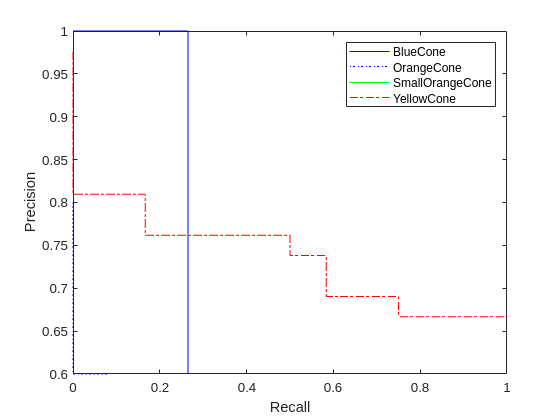

 results = table('Size',[height(testDataSet) 3],...
     'VariableTypes',{'cell','cell','cell'},...
     'VariableNames',{'Boxes','Scores','Labels'});
 % results = table('Size',[height(trainingData) 3],...
 %     'VariableTypes',{'cell','cell','cell'},...
 %     'VariableNames',{'Boxes','Scores','Labels'});

Save the images with detected objects into the Output folder.

today_date = string(datetime("now","Format","dd-MMM-uuuu"));

And loop through all the images in the test set.

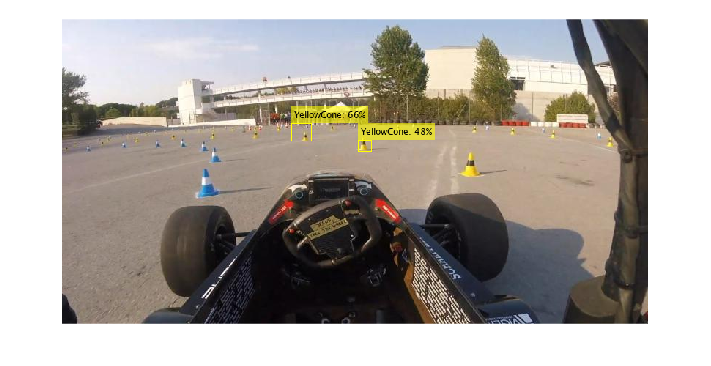

 threshold = 0.2;
 for i = 1:height(testDataSet)

     %Read the image
     I = imread(testDataSet.imageFilename{i});

     %Run the detector

     [bboxes,scores,labels] = detect(yolov4ConeDetector,I,"Threshold",threshold);

     %Collect the results in the results table
     %Select strongest detection
     results.Boxes{i} = floor(bboxes);
     results.Scores{i} = scores;
     results.Labels{i} = labels;

     if ~isempty(bboxes)
         annotations = string(labels) + ": " + (round(100*scores)) + "%";
         I = insertObjectAnnotation(I, "rectangle", bboxes, annotations);

         %%Write images with detected objects to the Output folder
         imgfilename = strcat('Image_',num2str(i),'_',today_date,'.png');
         imgOutFolder = fullfile(pwd,"Output/",imgfilename);
         imwrite(I,imgOutFolder);

     end

 end

 [ap,recall,precision] = evaluateDetectionPrecision(results, testDataSet(:,2:end),threshold);

 [am,fppi,missRate] = evaluateDetectionMissRate(results, testDataSet(:,2:end),threshold);

 figure
 plot(recall{1,1},precision{1,1},'b-',fppi{2,1},missRate{2,1},'b:',fppi{3,1},missRate{3,1},'g-',fppi{4,1},missRate{4,1},'r-.')
 hold on;
 xlabel('Recall')
 ylabel('Precision')
 legend('BlueCone','OrangeCone','SmallOrangeCone','YellowCone');

 % figure
 % loglog(fppi{1,1},missRate{1,1},'b-',fppi{2,1},missRate{2,1},'b:',fppi{1,1},missRate{3,1},'g-',fppi{4,1},missRate{4,1},'r-.')
 % hold on;
 % xlabel('False Positivies Per Image')
 % ylabel('Log Average Miss Rate')
 % legend('BlueCone','OrangeCone','SmallOrangeCone','YellowCone');

### Detect Objects in an image

img = imread("testimage.jpg");
[bboxes,scores,labels] = detect(yolov4ConeDetector,img,"Threshold",threshold);
if(~isempty(bboxes))
    annotations = string(labels) + ": " + (round(100*scores)) + "%";
    detectedimg = insertObjectAnnotation(img, 'rectangle', bboxes, annotations);
end
figure
imshow(detectedimg)

### Detect Object in a Video

Create video file reader for input

vidReader = VideoReader('Driverless_KIT_run_testvideo.mp4');
% vidReader = VideoReader('DV_Skidpad.mp4');

Create video player for visualization

vidPlayer = vision.DeployableVideoPlayer;

Initialize the detection result.

i = 1;
results = struct('Boxes',[],'Scores',[]);

Initialize a video writer object to save the video with detected objects.

todaydate = string(datetime("now","Format","dd-MMM-uuuu"));
videofilename = strcat("Video_",todaydate);
videoOutfolder = fullfile(pwd,"Output/",videofilename);
%MPEG-4 format is not supported in Linux
video_object = VideoWriter(videoOutfolder);
open(video_object);

Loop over the video and detect the objects

while(hasFrame(vidReader))    
    % GET DATA
    I = readFrame(vidReader);    

    % PROCESS
    [bboxes, scores,labels] = detect(yolov4ConeDetector,I,"Threshold",threshold);

    % Select strongest detection 
    [~,idx] = max(scores);
    results(i).Boxes = bboxes;
    results(i).Scores = scores;

    % VISUALIZE
    annotations = string(labels) + ": " + (round(100*scores(idx))) + "%";
    I = insertObjectAnnotation(I,'rectangle',bboxes,annotations);
    
    %%Save the frames with detected objects as video
    writeVideo(video_object,I);
    
    pause(0.1);
    step(vidPlayer,I);
    i = i+1;   
end
results = struct2table(results);
release(vidPlayer);
close(video_object);

### Supporting functions

% function data = augmentData(A)
% % Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% % scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% % jitter image color.
% 
% data = cell(size(A));
% for ii = 1:size(A,1)
%     I = A{ii,1};
%     bboxes = A{ii,2};
%     labels = A{ii,3};
%     sz = size(I);
% 
%     if numel(sz) == 3 && sz(3) == 3
%         I = jitterColorHSV(I,...
%             contrast=0.0,...
%             Hue=0.1,...
%             Saturation=0.2,...
%             Brightness=0.2);
%     end
% 
%     % Randomly flip image.
%     tform = randomAffine2d(XReflection=true,Scale=[1 1.1]);
%     rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
%     I = imwarp(I,tform,OutputView=rout);
% 
%     % Apply same transform to boxes.
%     [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
%     labels = labels(indices);
% 
%     % Return original data only when all boxes are removed by warping.
%     if isempty(indices)
%         data(ii,:) = A(ii,:);
%     else
%         data(ii,:) = {I,bboxes,labels};
%     end
% end
% end


function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    
    bboxes = data{num,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(num,1:2) = {I,bboxes};
end
end

## References

- Matlab Student Lounge: Yolov4 Object Detection

- Object Detection in Matlab: [Ground Truth for Object Detection](https://www.mathworks.com/matlabcentral/fileexchange/69180-using-ground-truth-for-object-detection)